# Ensemble Kalman Filter for Van der Pol model

cf. 片山徹	2011	非線形カルマンフィルタ，p.134

clc
clear
close all

global epsi
tic

M = 50; % the number of ensemble

## Equations of motion (discrete)

dxdt = @(x, dt) [x(:,1) + dt .* x(:,2), ...
    x(:,2) + dt .* (x(:,3) .* (1 - x(:,1).^2) .* x(:,2) - x(:,1)), ...
    x(:,3)];

% observation matrix
H = [0 1];

## true value and observations

epsi = 1.0;
q1 = 0.1; % process noise for x1
q2 = 0.1; % process noise for x2
Rt = 0.01; % observation noise 
dt = 0.1; % sampling time

x_ini = [0.2 0.1];
tspan = 0:dt:50;
[t_, x_] = ode45(@vanderpolEOM, tspan, x_ini);

tn_ = length(t_);
x_obs = (H * x_')' + sqrt(Rt) .* randn(tn_,1); % observation

## initial estimate

n = 3; % the number of state variables
P = 0.5 .* eye(n);
Q = diag([0.026 0.01 1e-5]);

x_est = zeros(tn_,n);

## EnKF

% initial ensemble matrix
XX = x_est(1,:) + sqrt(P(1,1)) .* randn(M, n);

for i = 1:tn_ - 1

### prediction step

    dt = t_(i+1) - t_(i);

    XX = dxdt(XX, dt);
%     add noise
    XX = XX + sqrt(dt) .* repmat(sqrt([Q(1,1), Q(2,2), Q(3,3)]), M, 1) .* randn(M,n);
    
    X0 = sum(XX,1) ./ (M - 1);
    Xe = XX - X0; % error ensemble matrix

    Pcov = (Xe' * Xe) ./ (M - 1);  % error covariance ensemble matrix

## filtering step

%     predicted output ensemble matrix
    YY = XX(:,2) + sqrt(Rt) .* randn(M,1);

    Y0 = sum(YY, 1) ./ (M - 1);
    Ye = YY - Y0;

    % Calculate correlation
    Pyy = (Ye' * Ye) ./ (M - 1);
    Pxy = (Xe' * Ye) ./ (M - 1);

%     kalman gain
    K = Pxy * Pyy^(-1); % nx1 vector
    
    XX = XX + K' .* (x_obs(i+1) - YY);
    X0 = sum(XX, 1) ./ (M - 1); % predicted error GRP

    x_est(i+1,:) = X0;
end

## data handling and show figures

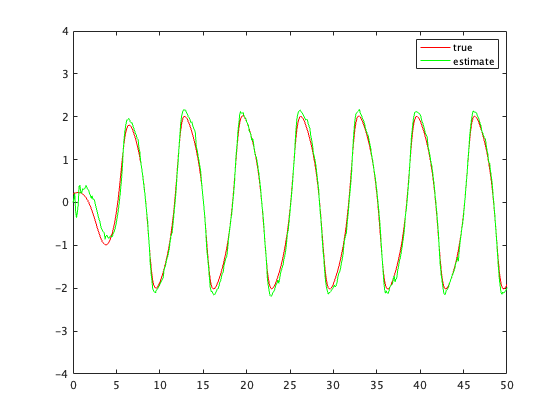

% estimation error
E = vecnorm(x_ - x_est(:,1:2), 2, 2);

% x_1
figure
plot(t_, x_(:,1),'r')
hold on
plot(t_, x_est(:,1), 'g')
legend('true', 'estimate')
ylim([-4 4])

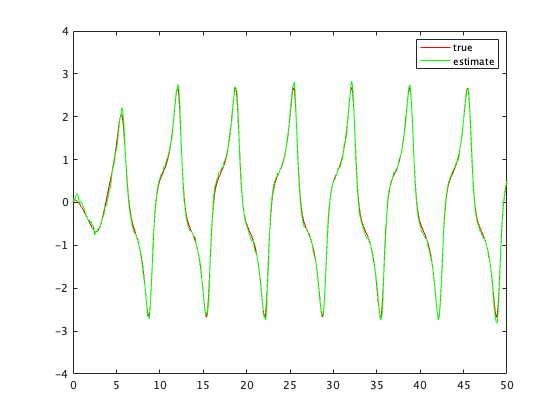


% x_2
figure
plot(t_, x_(:,2),'r')
hold on
plot(t_, x_est(:,2), 'g')
legend('true', 'estimate')
ylim([-4 4])

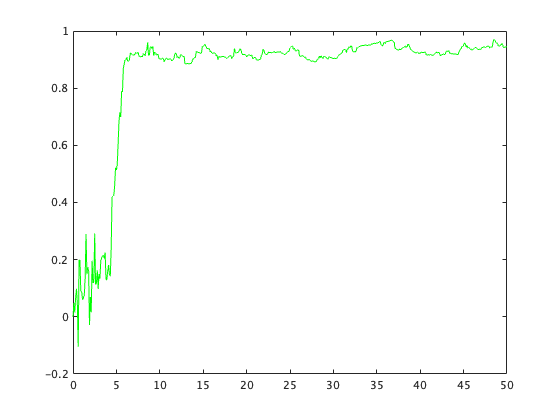


% x_3 = epsilon
figure
plot(t_, x_est(:,3), 'g')

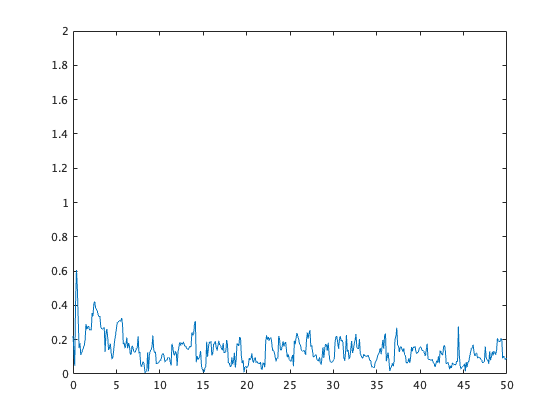


% estimation error
figure
plot(t_, E)
ylim([0 2])



toc

経過時間は 0.346012 秒です。
